# Práctica 7. Métodos para la búsqueda de raíces.

## Implementar varios métodos para buscar raíces de funciones reales.

**a)** Para una función $f:[a,b]\longrightarrow \mathbb{R}$ tal que $f(a)f(b)<0$, deseamos implementar el método de la bisección para encontrar una de sus raíces. Lo implementaremos en el **APÉNDICE A**. 

La función nos debe devolver, dadas $f$, $a$, $b$ y $tol$:

- Una raíz aproximada $x$ tal que $|x-\xi|<tol$.

**b)** Para una función $f:\mathbb{R} \longrightarrow \mathbb{R}$ contractiva, deseamos implementar el método del punto fijo para obtener un $x\in\mathbb{R}$ tal que $x\approx f(x)$. Lo implementaremos en el **APÉNDICE B**.

La función nos debe devolver, dados $f$, $x_0$, $N$ y $tol$:

- Un punto fijo $x$ tal que $|f(x)-x|<tol$, comenzando el algoritmo en el punto $x_0$.

- Si se sobrepasa el número máximo de iteraciones $N$ antes de llegar a la tolerancia deseada, un mensaje de error.

**c)** Para una función $f:\mathbb{R} \longrightarrow \mathbb{R}$, deseamos implementar el método de Newton para obtener un $x\in\mathbb{R}$ tal que$f(x)\approx 0$ . Lo implementaremos en el **APÉNDICE C**.

La función nos debe devolver, dados $f$, $x_0$, $N$ y $tol$:

- Una raíz aproximada $x_n$ tal que $|x_n-x_{n-1}|<tol$, comenzando el algoritmo en el punto $x_0$.

- Si se sobrepasa el número máximo de iteraciones $N$ antes de llegar a la tolerancia deseada, un mensaje de error.

**d)** Calcula una raíz aproximada de la función $f(x)=sin(x^2)$ en el intervalo $[-2,1]$ por los tres métodos con una precisión de $tol=10^{-4}$ y compara los resultados.

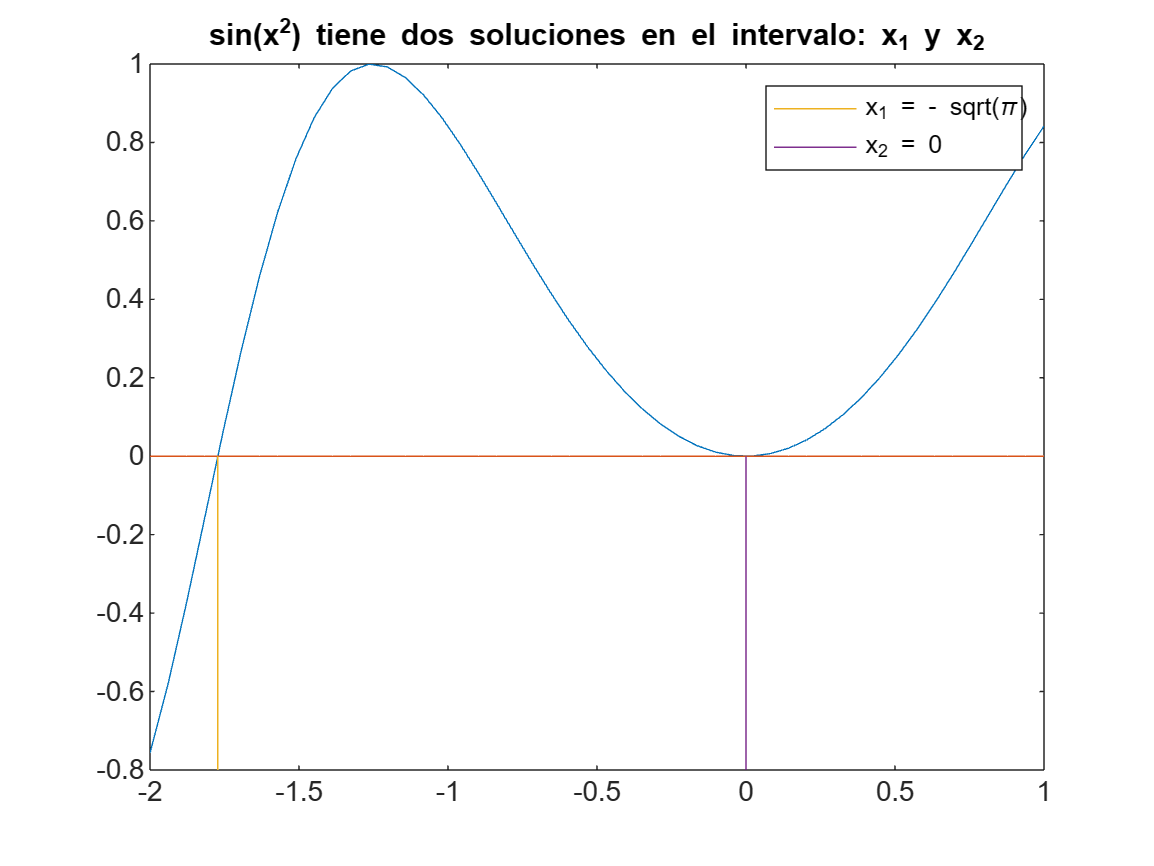

z = linspace(-2,1,50);
f = @(x) sin(x.^2);
plot(z,f(z),z,zeros(length(z)), [-sqrt(pi),-sqrt(pi)],[-0.8,0],[0,0],[-0.8,0]);
title("sin(x^2) tiene dos soluciones en el intervalo: x_1 y x_2")
legend('','',"x_1 = - sqrt(\pi)", "x_2 = 0")


tol = 10^(-4);
a = -2;
b = 1;
x = raizBiseccion(f,a,b,tol);
fprintf("Usando método de la bisección: %d", x);

Usando método de la bisección: -1.772400e+00

% Vemos que está aproximando x1 = -sqrt(pi)
-sqrt(pi)

ans = -1.7725

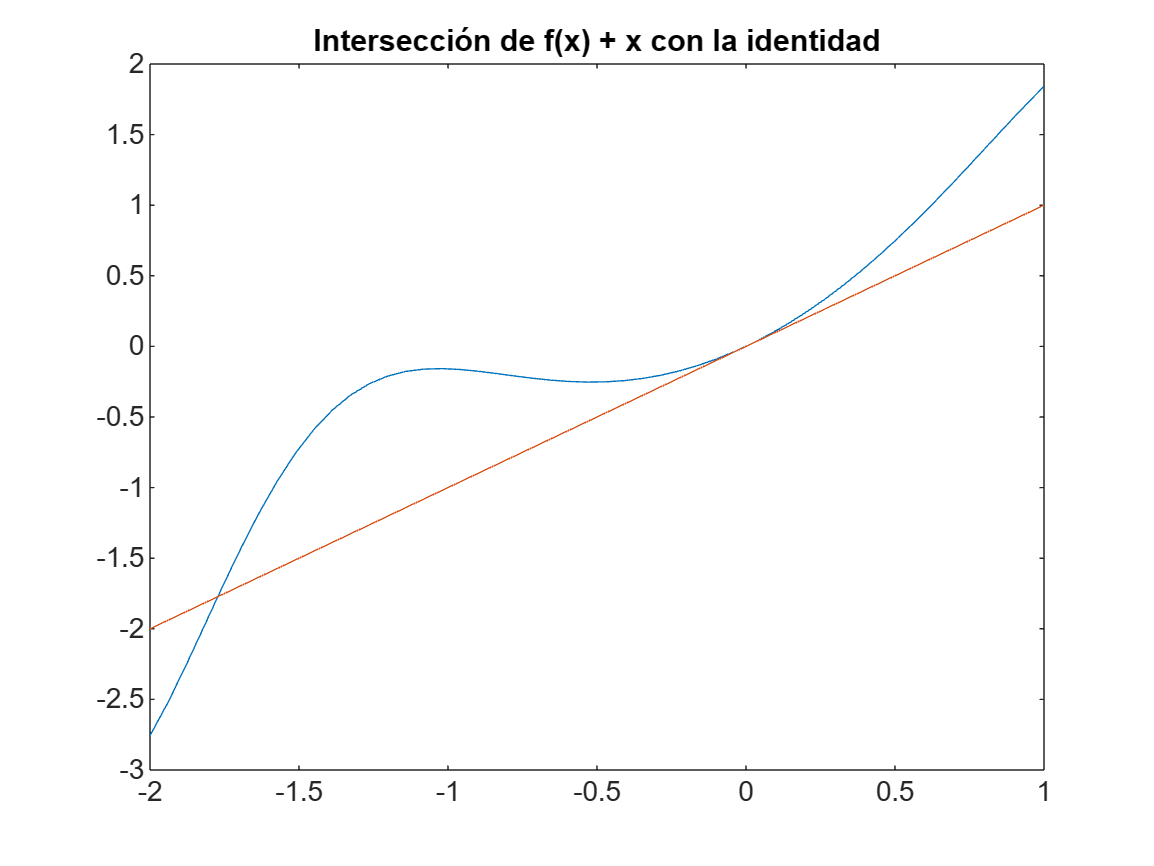

plot(z,f(z)+z,z,z)
title("Intersección de f(x) + x con la identidad")

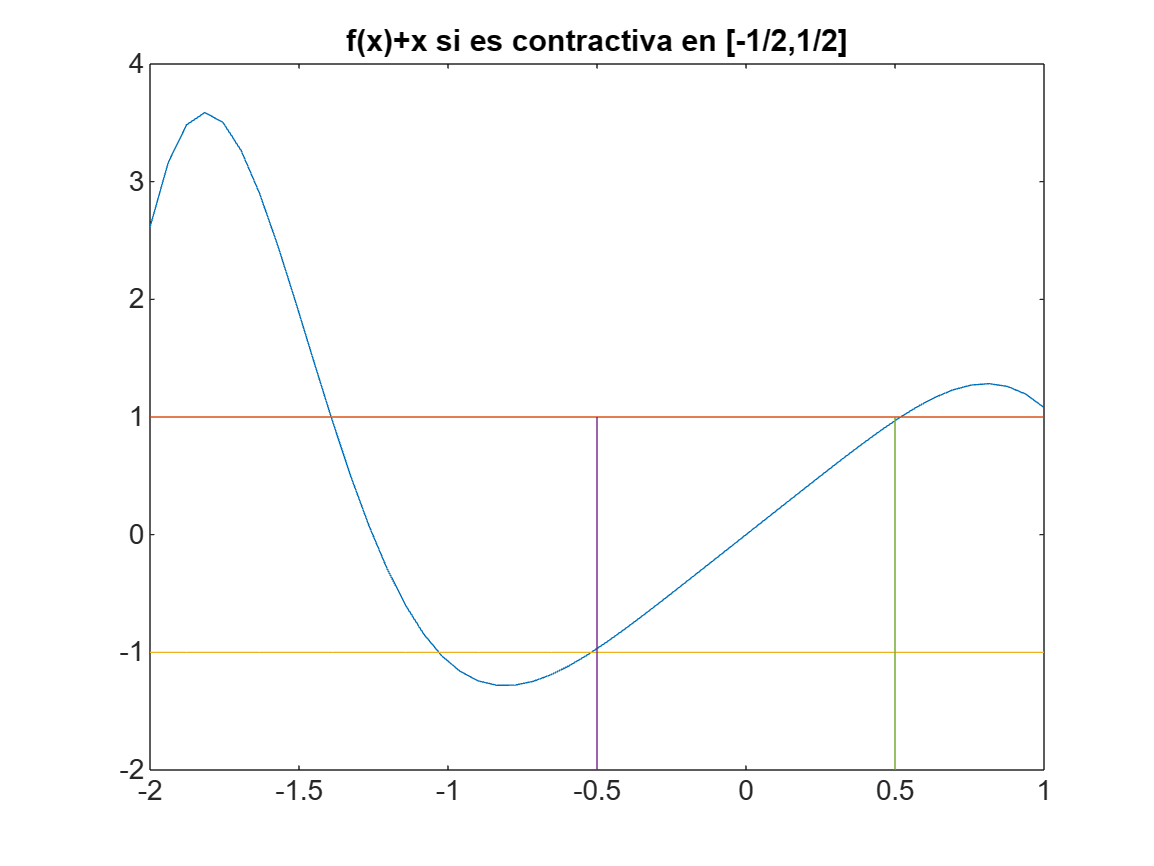

x = raizPuntofijo(f, (a+b)/2, 10^3, tol);
% observamos que f(x) + x no es contractiva en todo [-2,1]
plot(z,2*z.*cos(z.^2),z,ones(length(z)),z,-1*ones(length(z)),[-0.5,-0.5],[-2,1],[0.5,0.5],[-2,1]);
title("f(x)+x si es contractiva en [-1/2,1/2]")

Aún así, no podemos garantizar que el método vaya a converger, pues $f\left(\left\lbrack -\frac{1}{2},\frac{1}{2}\right\rbrack \right)\not\subset \left\lbrack -\frac{1}{2},\frac{1}{2}\right\rbrack$y no podemos aplicar el Teorema del Punto Fijo.

fprintf("Usando método del punto fijo: %d", x);

Usando método del punto fijo: -9.866662e-03

% vemos que está aproximando x2 = 0

x = raizNewton(f, (a+b)/2, 10^3, tol);
fprintf("Usando método de Newton: %d", x);

Usando método de Newton: -5.965481e-05

% vemos que está aproximando x2 =  0

### Apéndice A. Método de la bisección.

function x = raizBiseccion(f,a,b,tol)
    N = ceil((log(b-a) - log(tol)) / log(2)) - 1;
    if (f(a) == 0) x = a; return; end;
    if (f(b) == 0) x = b; return; end;
    A = a; B = b; X = 0;
    for i = 1:N
        X = (A + B) / 2;
        fX = f(X);
        if(fX == 0) x = X; return; end;
        if (fX * f(A) < 0)
            B = X;
        else A = X;
        end;
    end
    x = X;
end

### Apéndice B. Método de punto fijo

$f(x)=0 \Leftrightarrow g(x)=f(x)+x=x $ Buscamos punto fijo a la función g

function x = raizPuntofijo(g,x0,N,tol)
    f = @(x) g(x) + x;
    x = x0;
    for i = 1:N
        fX = f(x);
        if (norm(x - fX) < tol) x = fX; return; end;
        x = fX;
    end
    assert(false, "Se ha excedido el número de iteraciones");
end

### Apéndice C. Método de Newton.

function x = raizNewton(f,x0,N,tol)
    df = @(x) double(subs(diff(sym(f)),x));
    x = x0;
    for i = 1:N
        xSig = x - f(x) / df(x);
        if(norm(xSig - x) < tol) x = xSig; return; end;
        x = xSig;
    end
    assert(false, "Se ha excedido el número de iteraciones");
end